# visualizing real B_sec(t) 

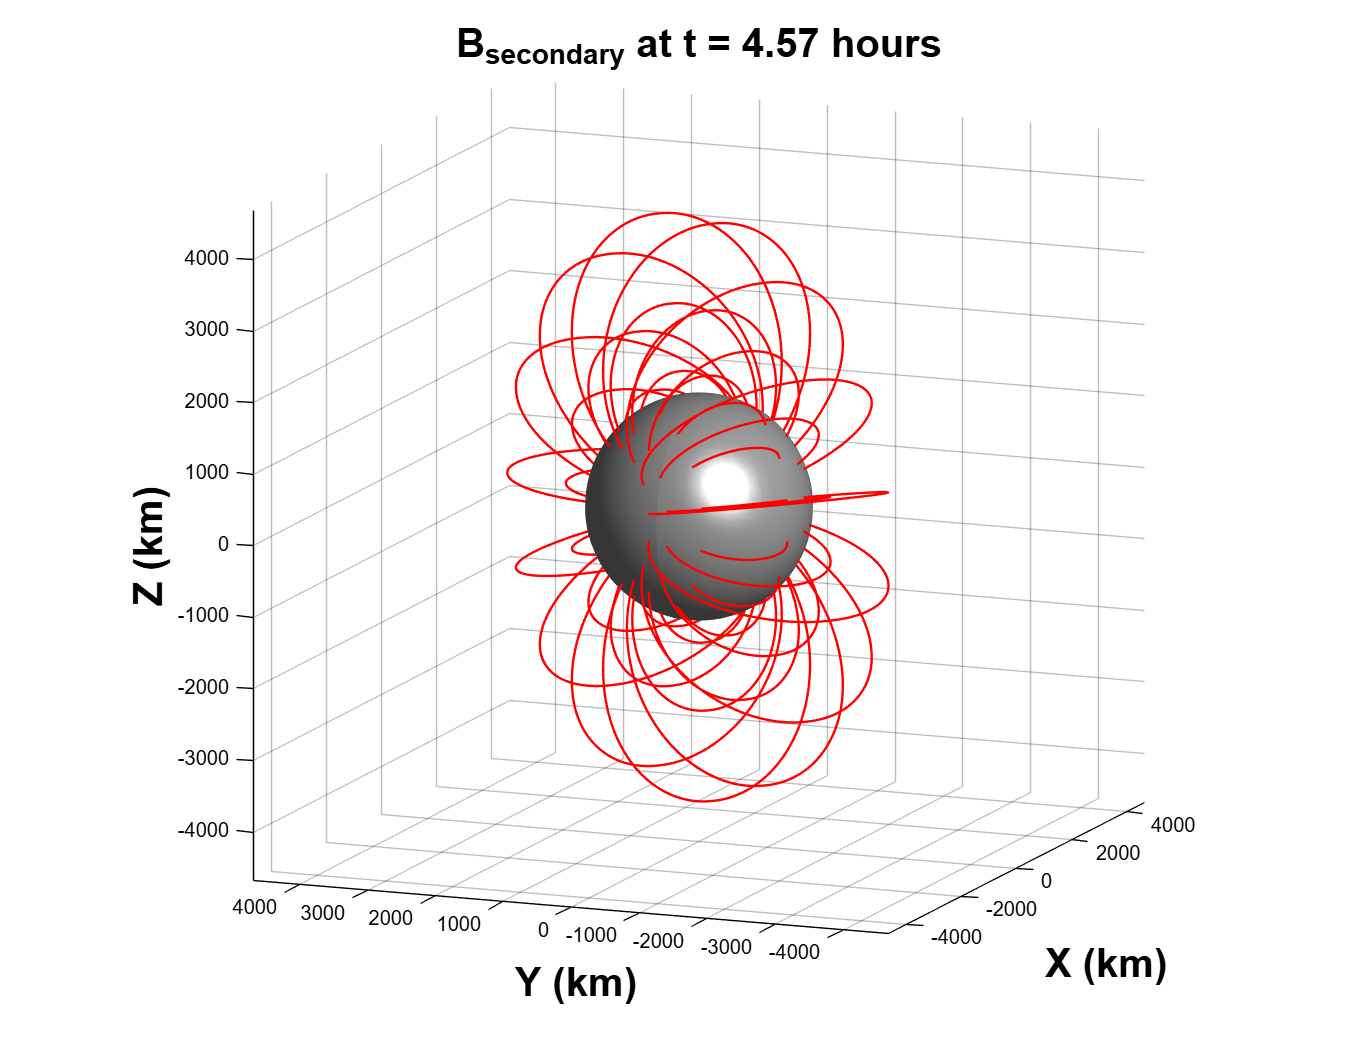

clear
% define constants
r_m = 1560; % Europa radius (km)
B_prim = 250; % background field amplitude nT
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)

% inducing field direction 
e0x = [1;0;0];
e0y = [0;1;0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create 3D spatial grid
grid_limit = 3 * r_m; % view up to 3 planetary radii out
num_points = 35; % spatial grid resolution
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));

% set up animation time array (60 steps over one full period)
num_frames = 60;
time_steps = linspace(0, synodic_period, num_frames);

% setup figure window
fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% animation loop
for t = time_steps
    
    % 3D vector fields
    Bx = zeros(size(X)); By = zeros(size(Y)); Bz = zeros(size(Z));
    
    % compute the current direction of the secondary dipole axis (m_hat)
    m_hat = [cos(omega*t - phi); sin(omega*t - phi); 0];
    m_hat = m_hat / norm(m_hat); 
    
    % calculate the 3D secondary field across the meshgrid
    for i = 1:numel(X)
        r_vec = [X(i); Y(i); Z(i)];
        r = norm(r_vec);
        
        % avoid division by zero
        if r < 1e-3
            r = 1e-3;
        end
        
        % X EQUATION
        r_dot_e0x = dot(r_vec, e0x);
        spatial_bracketx = 3 * r_dot_e0x * r_vec - (r^2) * e0x;
        coefx = - (A * B_prim * r_m^3) * (cos(omega * t - phi)) / (2 * r^5);
        
        % Y EQUATION
        r_dot_e0y = dot(r_vec, e0y);
        spatial_brackety = 3 * r_dot_e0y * r_vec - (r^2) * e0y;
        coefy = - (A * B_prim * r_m^3) * (sin(omega * t - phi)) / (2 * r^5);
        
        % store vector components
        B_vector = (coefx * spatial_bracketx) + (coefy * spatial_brackety);
        Bx(i) = B_vector(1);
        By(i) = B_vector(2);
        Bz(i) = B_vector(3);
    end
    
    % reset frame
    clf; 
    set(gcf, 'Color', 'w');
    
    % seed finding for magnetic equator 
    v1 = cross(m_hat, [0; 0; 1]); 
    v1 = v1 / norm(v1);           % perpendicular vector in the XY plane
    v2 = [0; 0; 1];               % z-axis orthogonal vector
    
    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    
    % generate 3 rings of seeds to capture close, mid, and far field lines
    radii_layers = [1.2, 1.8, 2.6] * r_m;
    
    seed_X = []; seed_Y = []; seed_Z = [];
    
    for r_seed = radii_layers
        for k = 1:length(theta)
            pt = r_seed * (cos(theta(k))*v1 + sin(theta(k))*v2);
            seed_X = [seed_X, pt(1)];
            seed_Y = [seed_Y, pt(2)];
            seed_Z = [seed_Z, pt(3)];
        end
    end
    
    % making Europa
    [sph_X, sph_Y, sph_Z] = sphere(50);
    surf(sph_X * r_m, sph_Y * r_m, sph_Z * r_m, 'FaceColor', [0.7 0.7 0.7], ...
         'EdgeColor', 'none', 'FaceAlpha', 1.0);
    hold on;
    camlight('headlight'); lighting gouraud; % made opaque and 3d looking
    
    % trace streamlines
    h1 = streamline(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    h2 = streamline(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));
    set(h1, 'Color', 'r', 'LineWidth', 1.2);
    set(h2, 'Color', 'r', 'LineWidth', 1.2);

    axis equal; grid on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
    
    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', 'Color', 'w'); 
    xlabel('X (km)', 'Color', 'k', 'FontSize', 20, 'FontWeight', 'bold');
    ylabel('Y (km)', 'Color', 'k', 'FontSize', 20, 'FontWeight', 'bold');
    zlabel('Z (km)', 'Color', 'k', 'FontSize', 20, 'FontWeight', 'bold');
    
    view([-68 12]); 
    title(sprintf('B_{secondary} at t = %.2f hours', t/3600), ...
          'Color', 'k', 'FontSize', 20, 'FontWeight', 'bold');
    
    drawnow;
    pause(0.03);
end